# Análisis de un cuarto de pruebas térmicas


syms t s % t = tiempo , s = variable compleja
m = 70 * heaviside(t); % Entrada
mf = 0.5/(10*s+1); % Función de transferencia aplicada a la entrada


## Caso a) Puerta cerrada


outputa = (laplace(m) * mf); % señal de salida

outputa

$$outputa = \frac{35}{s\,\left(10\,s+1\right)}$$


temperaturaCuarto = ilaplace(outputa); % inversa de laplace en la salida
%Perfecto porque la temperatura inical del cuarto es cero
temperaturaCuarto

$$temperaturaCuarto = 35-35\,{\mathrm{e}}^{-\frac{t}{10}}$$

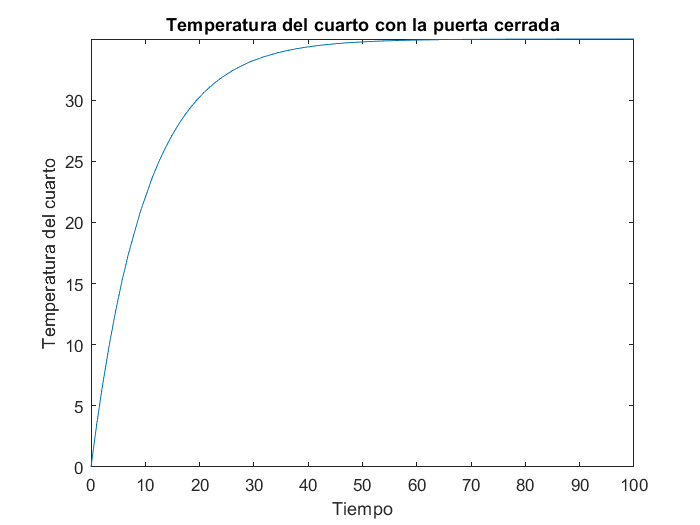


fplot(temperaturaCuarto, [0 100]);
title('Temperatura del cuarto con la puerta cerrada')
xlabel('Tiempo') 
ylabel('Temperatura del cuarto') 

## Caso b) Asumiendo que la temperatura inicial del cuarto es de 20

inicialTemp = 20 * heaviside(t); % Temperatura inicial del cuarto 

outputb = (laplace(m) * mf) + laplace(inicialTemp); % Señal de salida

outputb

$$outputb = \frac{35}{s\,\left(10\,s+1\right)}+\frac{20}{s}$$


temperaturaCuartob = ilaplace(outputb); % Inversa de la
% Tiene sentido porque la temperatura inicial es de 20C
temperaturaCuartob

$$temperaturaCuartob = 55-35\,{\mathrm{e}}^{-\frac{t}{10}}$$

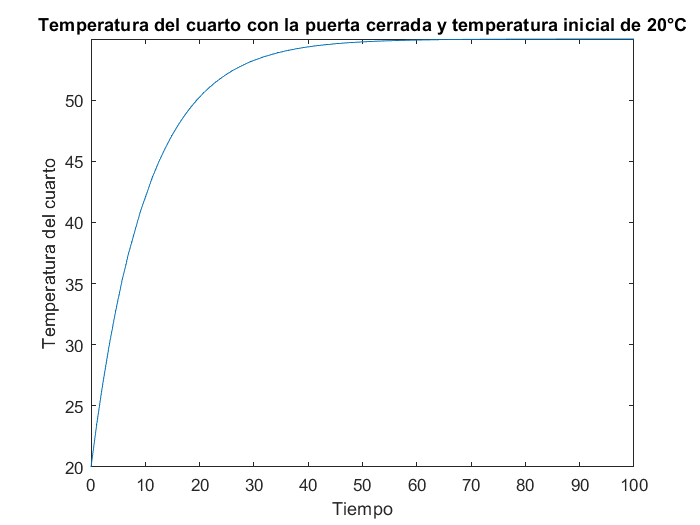


fplot(temperaturaCuartob, [0 100]);
title('Temperatura del cuarto con la puerta cerrada y temperatura inicial de 20°C')
xlabel('Tiempo') 
ylabel('Temperatura del cuarto') 

## Caso c) Mismo caso b, pero agregando que la puerta se abre después de dos minutos

d = 60 * heaviside(t - 2); % Señal de perturbación 
df = 0.1/(10*s + 1); % Función de transferencia aplicada a la perturbación 

outputc =  -(laplace(d) * df) + laplace(m) * mf + laplace(inicialTemp) % Salida

$$outputc = \frac{35}{s\,\left(10\,s+1\right)}+\frac{20}{s}-\frac{6\,{\mathrm{e}}^{-2\,s}}{s\,\left(10\,s+1\right)}$$


temperaturaCuartoc = ilaplace(outputc); % Inversa de laplace
  
temperaturaCuartoc

$$temperaturaCuartoc = 6\,\mathrm{heaviside}\left(t-2\right)\,\left({\mathrm{e}}^{\frac{1}{5}-\frac{t}{10}}-1\right)-35\,{\mathrm{e}}^{-\frac{t}{10}}+55$$

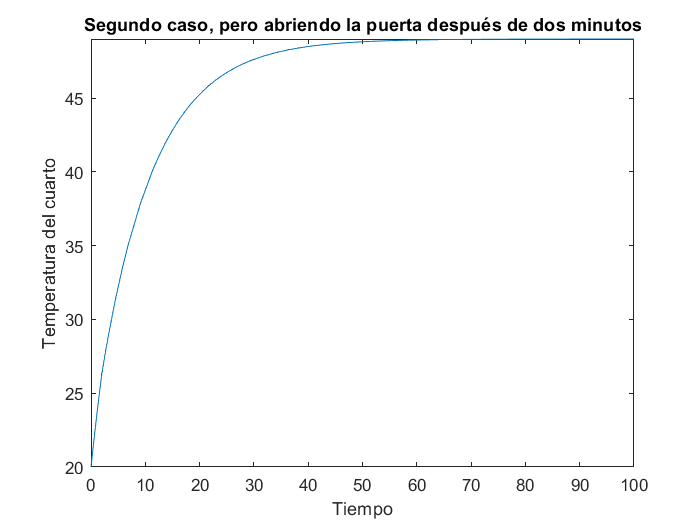

% Tiene sentido la temperatura es menor que con la puerta cerrada
fplot(temperaturaCuartoc, [0, 100]);

title('Segundo caso, pero abriendo la puerta después de dos minutos')
xlabel('Tiempo') 
ylabel('Temperatura del cuarto') 